clc; clear; close all
rng("default")

# Load 1D-FC Data

f = @(x, y) 4 + (1 + x.^2 + y.^2).*(sin(2.5*pi*x - 0.5) + cos(2*pi*y - 0.5))

f = function_handle with value:
    @(x,y)4+(1+x.^2+y.^2).*(sin(2.5*pi*x-0.5)+cos(2*pi*y-0.5))


l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

C = 27;
d = 8;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

# Constructing Boundary Patch

## C2 Patch

Needs l(theta) data, the corners on the boundary in terms of theta, and function values on mesh

C2_patch = construct_C2_patch(f, 0.4, 2*pi-0.4, 0, 20, 20); % data associated with patch

[X, Y] = C2_patch.xy_mesh();
figure;
scatter(X(:), Y(:));
hold on;

## S Patch

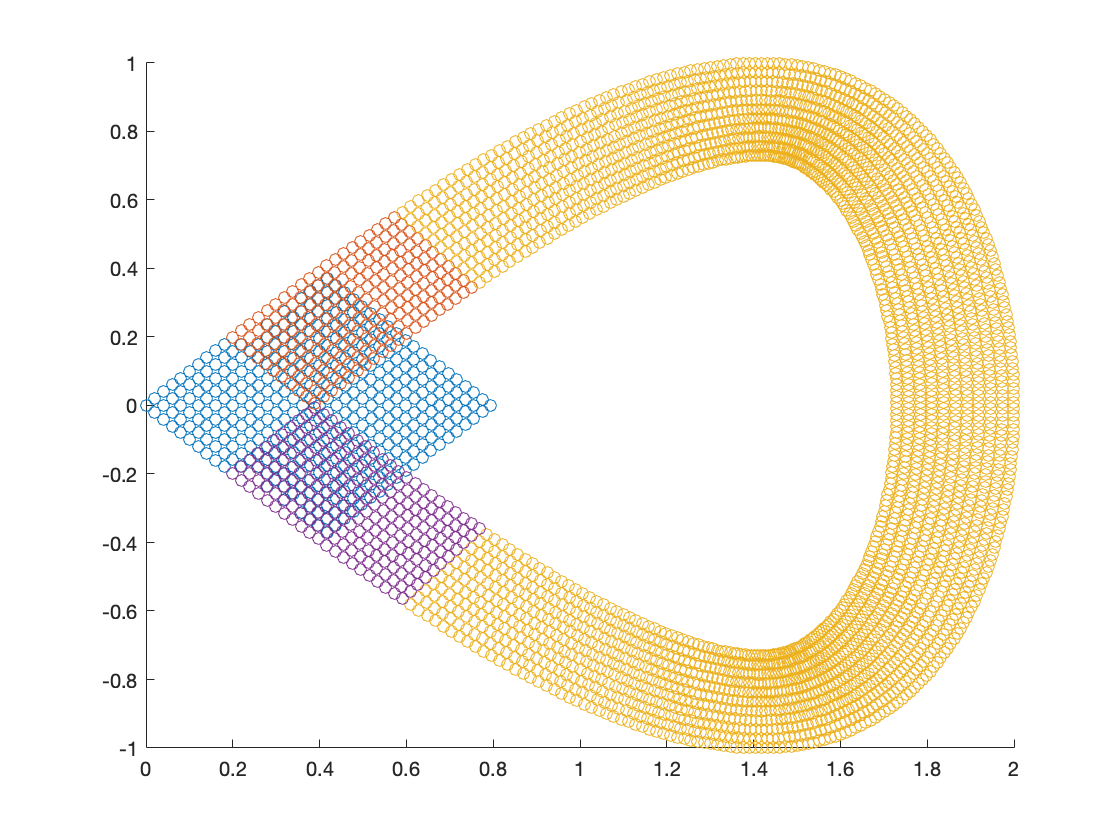

window_patch_xi = construct_S_patch(f, 0.2, 0.6, 0.027, 20, 10);
window_patch_eta = construct_S_patch(f, 2*pi-0.2, 2*pi-0.6, 0.027, 20, 10);
S_patch = construct_S_patch(f, 0.6, 2*pi-0.6, 0.027, 255, 10);

[X, Y] = window_patch_eta.xy_mesh();
scatter(X(:), Y(:))

[X, Y] = S_patch.xy_mesh();
scatter(X(:), Y(:))

[X, Y] = window_patch_xi.xy_mesh();
scatter(X(:), Y(:))

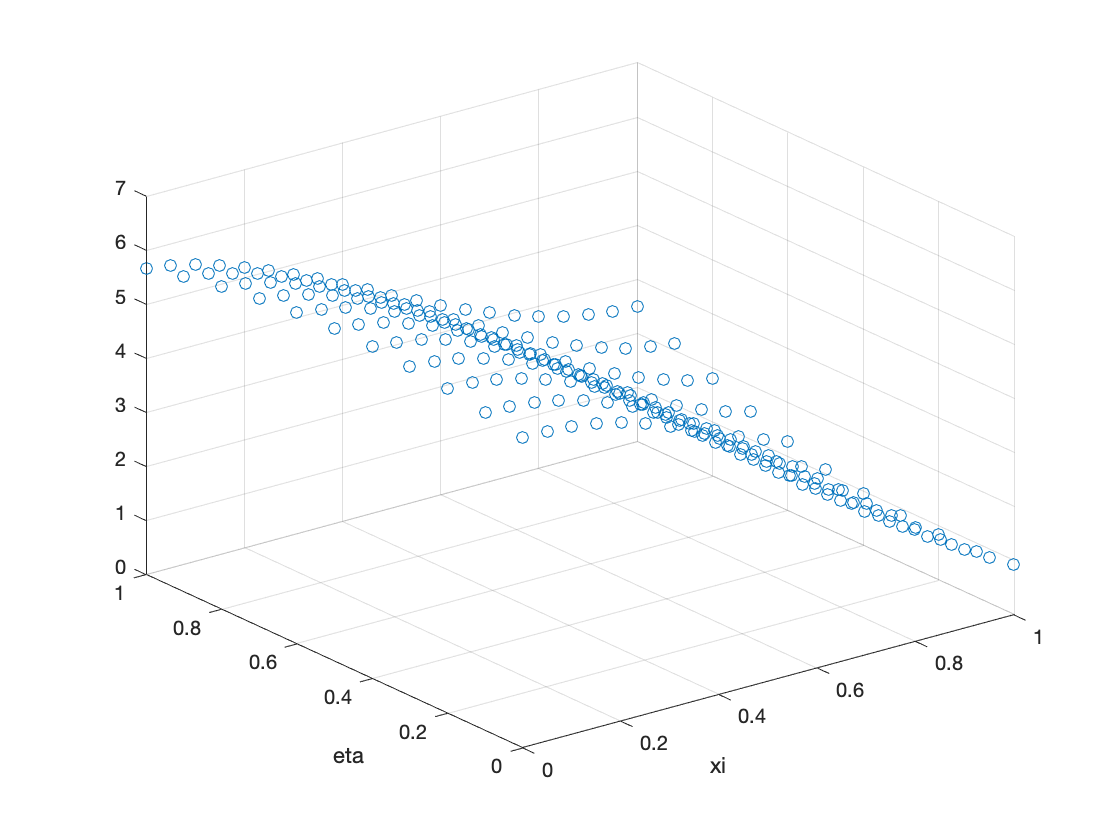


[C2_norm, xi_norm, eta_norm] = C2_patch.compute_phi_normalization(window_patch_xi, window_patch_eta);

[XI, ETA] = window_patch_eta.xi_eta_mesh();
phi_normalized = window_patch_eta.f_XY;%.*window_patch_eta.window_phi(XI, ETA)./eta_norm;
figure;
scatter3(XI(:), ETA(:), phi_normalized(:))
xlabel('xi')
ylabel('eta')

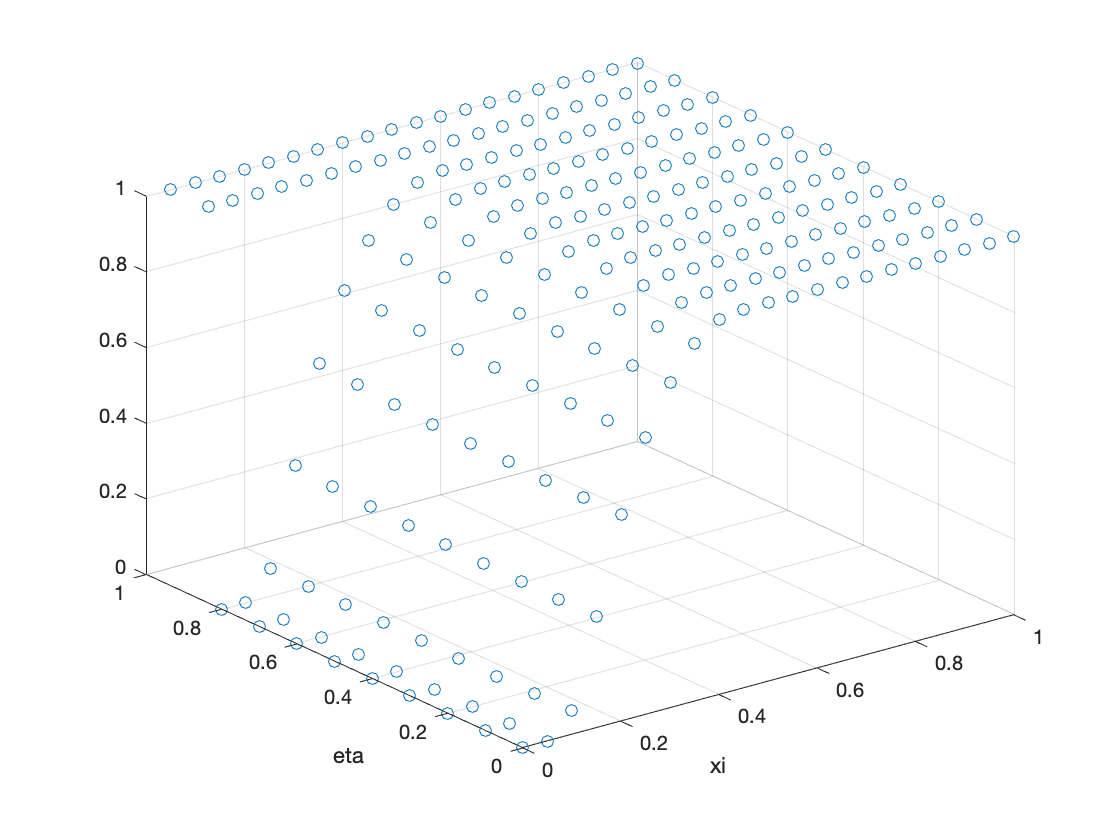


[XI, ETA] = window_patch_eta.xi_eta_mesh();
phi_normalized = window_patch_eta.window_phi(XI, ETA)./eta_norm;
figure;
scatter3(XI(:), ETA(:), phi_normalized(:))
xlabel('xi')
ylabel('eta')


figure;
phi_normalized = window_patch_eta.f_XY.*phi_normalized

phi_normalized =          0    0.0023    0.3588    1.6603    3.0144    3.9344    4.4760    4.7233    4.7029    4.4709    4.1709    3.8488    3.5101    3.1600    2.8047    2.4506    2.1044    1.7729    1.4631    1.1817    0.9351
         0    0.0024    0.3672    1.6937    3.0652    3.9877    4.5215    4.7559    4.7206    4.4720    4.1535    3.8144    3.4605    3.0975    2.7318    2.3701    2.0192    1.6861    1.3776    1.1004    0.8606
         0    0.0024    0.3751    1.7234    3.1063    4.0261    4.5494    4.7705    4.7230    4.4624    4.1312    3.7810    3.4181    3.0486    2.6790    2.3161    1.9668    1.6380    1.3363    1.0681    0.8392
         0    0.0025    0.3827    1.7497    3.1379    4.0498    4.5599    4.7679    4.7109    4.4434    4.1051    3.7500    3.3846    3.0150    2.6480    2.2903    1.9487    1.6299    1.3402    1.0855    0.8714
         0    0.0025    0.3900    1.7728    3.1603    4.0593    4.5538    4.7490    4.6855    4.4162    4.0768    3.7230    3.3613    2.998

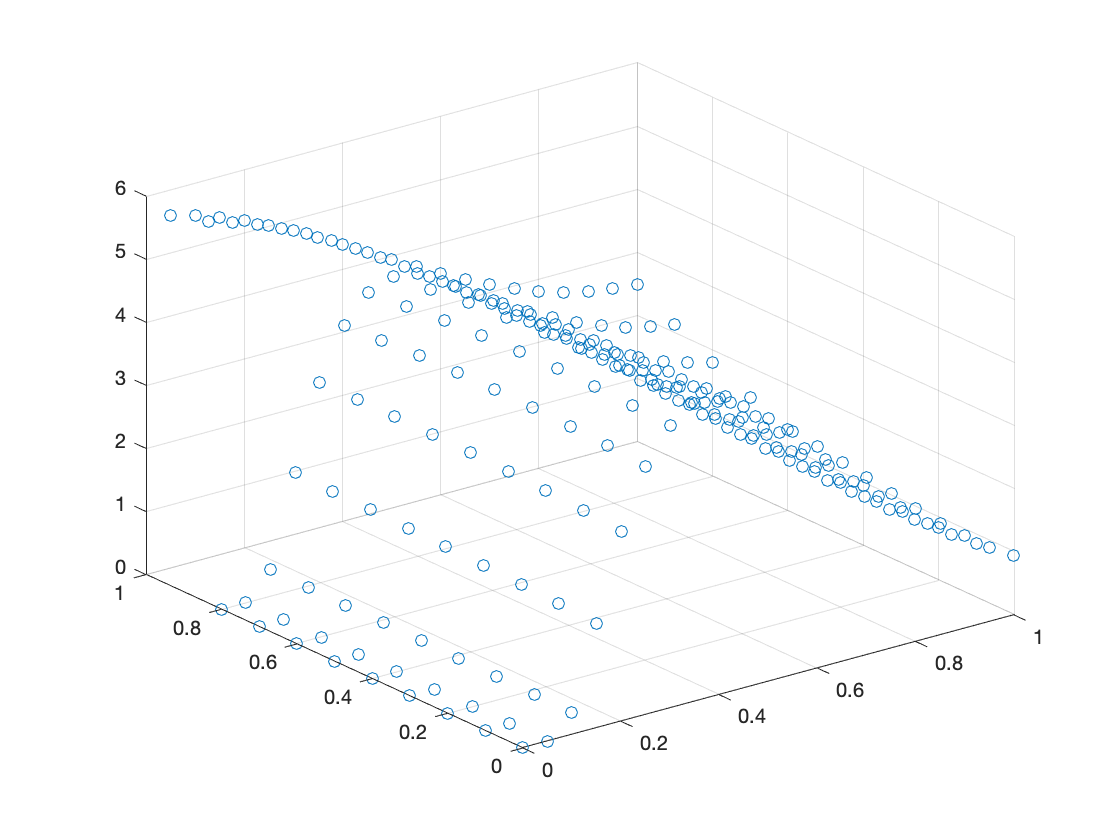

scatter3(XI(:), ETA(:), phi_normalized(:))


% [XI, ETA] = C2_patch.xi_eta_mesh();
% normalized_phi = C2_patch.phi(XI, ETA)./C2_norm;
% 
% figure;
% scatter3(XI(:), ETA(:), normalized_phi(:))
% xlabel("xi")
% ylabel("eta")
% 
% 
% figure;
% [XI, ETA] = window_patch_eta.xi_eta_mesh();
% normalized_phi = window_patch_eta.window_phi(XI, ETA)./xi_norm;
% figure;
% scatter3(XI(:), ETA(:), normalized_phi(:))

# FC on C2 Patch and S Patch

Assumes we know what type the patches are, if not, we can simply add another entry that is enumeration of the patch types

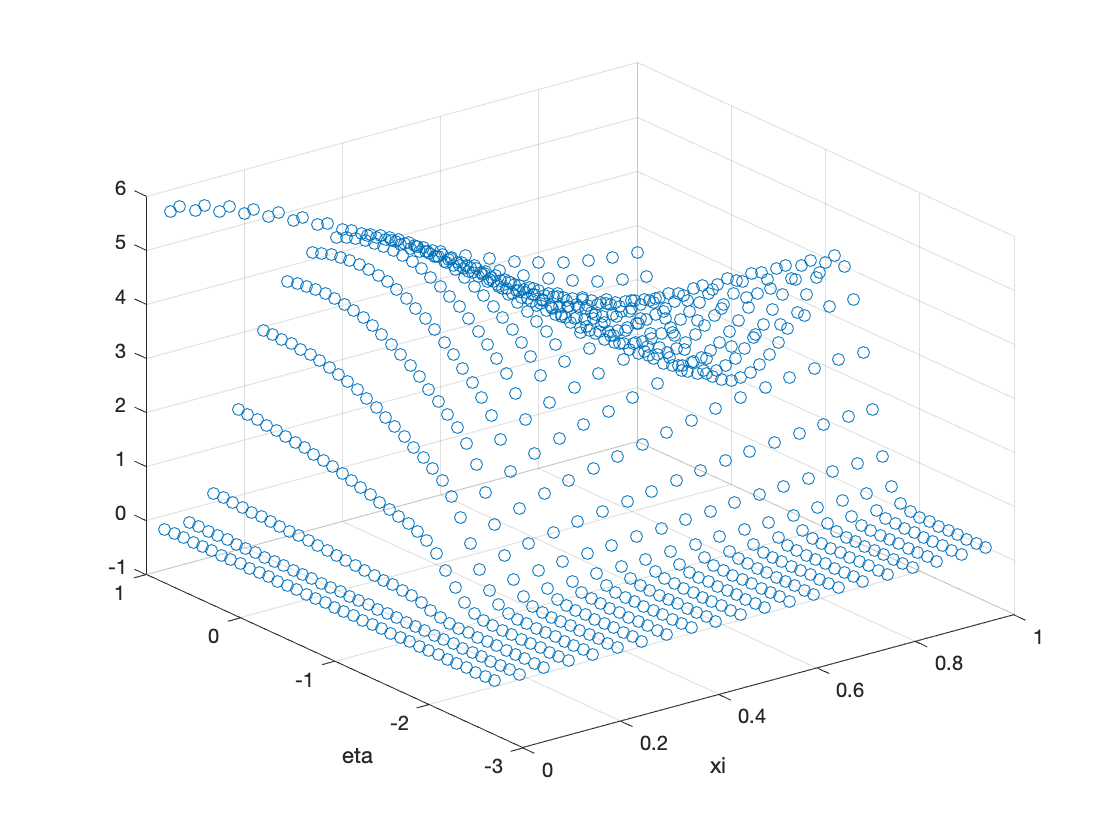

% creates patch with data, including partition of unity
C2_fcont_patch = C2_patch.FC(C, d, A, Q, C2_norm);
window_fcont_patch_xi = window_patch_xi.FC(C, d, A, Q, xi_norm);
window_fcont_patch_eta = window_patch_eta.FC(C, d, A, Q, eta_norm);
S_fcont_patch = S_patch.FC(C, d, A, Q, nan);

[XI, ETA] = window_fcont_patch_eta.xi_eta_mesh();
figure;
scatter3(XI(:), ETA(:), window_fcont_patch_eta.f_XY(:))
xlabel("xi")
ylabel("eta")

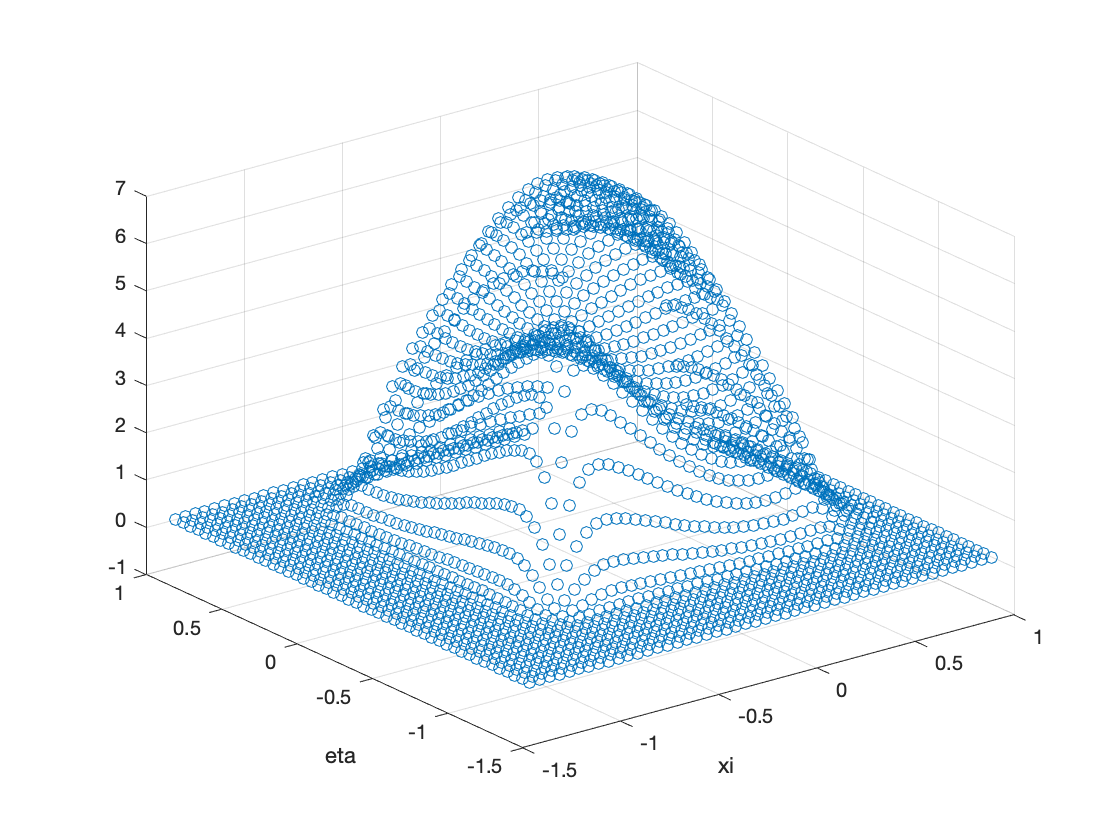


[XI, ETA] = C2_fcont_patch.xi_eta_mesh();
figure;
scatter3(XI(:), ETA(:), C2_fcont_patch.f_XY(:))
xlabel("xi")
ylabel("eta")

# Interpolation onto R

Note that we don't have any interior patches, so if any points aren't in the C2 or S patch, we just assume we know the value.

R_x_bounds = [C2_fcont_patch.x_min, S_fcont_patch.x_max];
R_y_bounds = [S_fcont_patch.y_min, S_fcont_patch.y_max];

n_R = 80;
h_R_x = (R_x_bounds(2) - R_x_bounds(1))/n_R

h_R_x = 0.0474

h_R_y = (R_y_bounds(2) - R_y_bounds(1))/n_R

h_R_y = 0.0432


[R_X, R_Y] = meshgrid(linspace(R_x_bounds(1), R_x_bounds(2), n_R+1), linspace(R_y_bounds(1), R_y_bounds(2), n_R+1));
f_R = zeros(size(R_X));

theta_mesh = transpose(linspace(0, 2*pi, 100));
boundary_XY = l_theta(theta_mesh);
interior_polygon = inpolygon(R_X, R_Y, boundary_XY(:, 1), boundary_XY(:, 2));

for i = 1:size(R_X, 1)
    for j = 1:size(R_X, 2)
        x = R_X(i, j);
        y = R_Y(i, j);
        
        if interior_polygon(i, j)
            f_R(i, j) = f(x, y);
        else
            [f_S, ~, in_range_S] = S_fcont_patch.locally_compute(x, y, d);            
            if in_range_S
                f_R(i, j) = f_S;
            else
                [f_C2, ~, in_range_C2] = C2_fcont_patch.locally_compute(x, y, d+1);
                [f_window_xi, ~, in_range_xi] = window_fcont_patch_xi.locally_compute(x, y, d+1);
                [f_window_eta, ~, in_range_eta] = window_fcont_patch_eta.locally_compute(x, y, d+1);
                
                if in_range_C2
                    f_R(i, j) = f_R(i, j) + f_C2;
                end
                if in_range_xi
                    f_R(i, j) = f_R(i, j) + f_window_xi;
                end
                if in_range_eta
                    f_R(i, j) = f_R(i, j) + f_window_eta;
                end
            end     
        end
    end
end

f_R

f_R =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0000   -0.0000    0.0000   

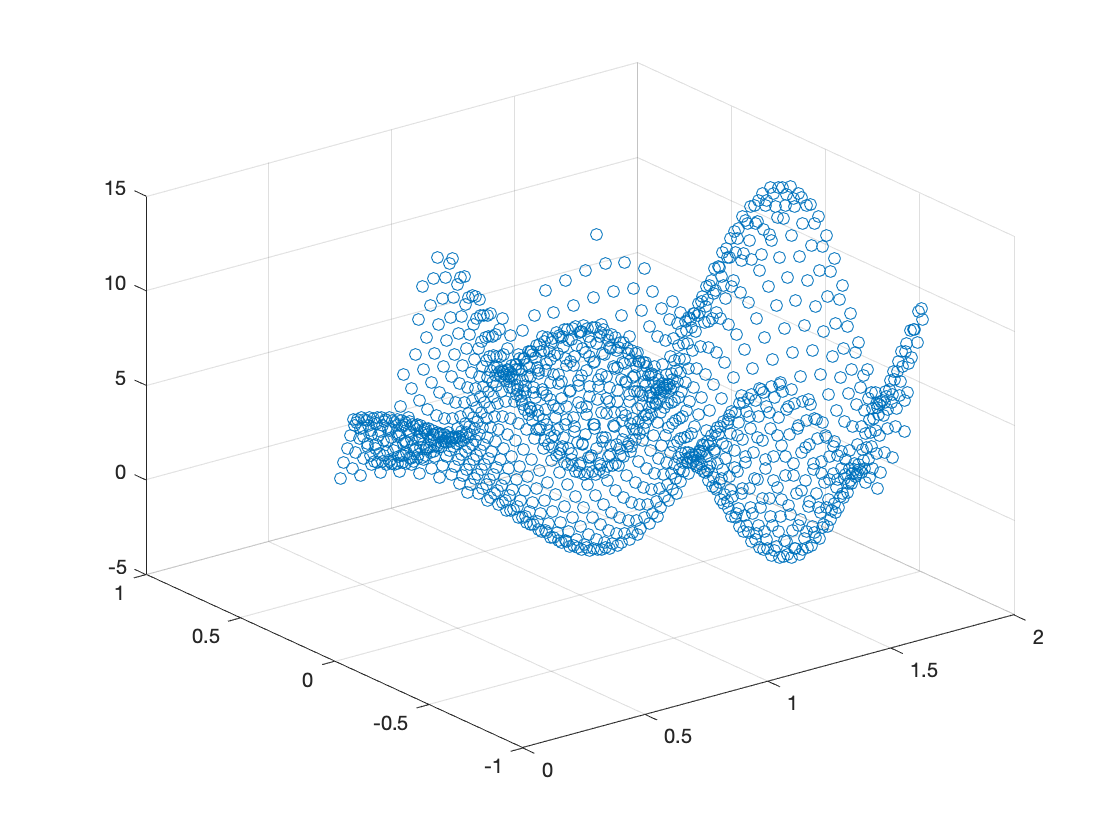

[XI, ETA] = S_patch.xi_eta_mesh();

f_R_XY = f(R_X, R_Y);
figure;
scatter3(R_X(interior_polygon), R_Y(interior_polygon), f_R_XY(interior_polygon))

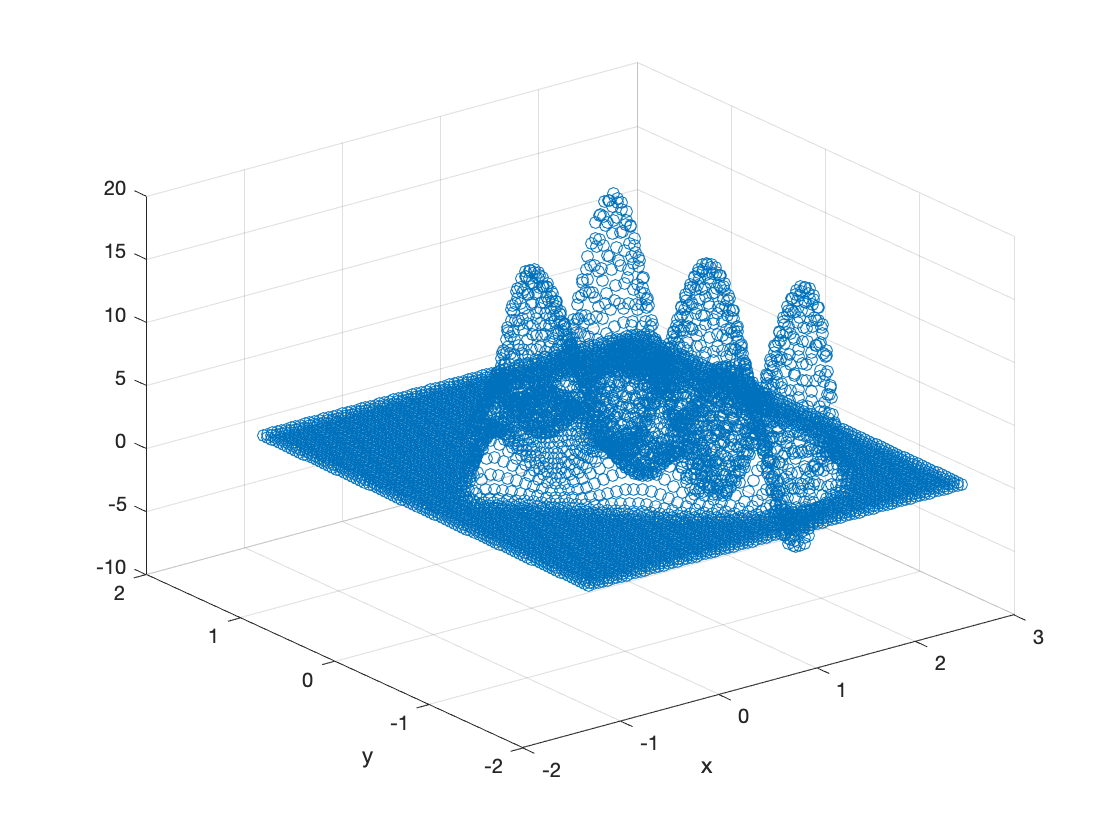

figure;
scatter3(R_X(:), R_Y(:), f_R(:))
xlabel("x")
ylabel('y')

# FFT

fc_coeffs = fft2(f_R)./numel(f_R)

fc_coeffs =    1.6846 + 0.0000i  -0.8021 + 0.5043i  -0.2541 - 0.0954i  -0.1285 - 0.2548i   0.4400 - 0.3831i   0.2241 + 0.6128i  -0.3246 + 0.0012i  -0.0697 - 0.1087i   0.0068 - 0.0653i   0.0345 - 0.0234i   0.0332 + 0.0056i   0.0181 + 0.0181i   0.0014 + 0.0169i  -0.0092 + 0.0088i  -0.0113 + 0.0004i  -0.0072 - 0.0047i  -0.0016 - 0.0059i   0.0024 - 0.0039i   0.0039 - 0.0010i   0.0030 + 0.0011i   0.0011 + 0.0018i  -0.0005 + 0.0016i  -0.0012 + 0.0008i  -0.0011 - 0.0001i  -0.0006 - 0.0005i  -0.0000 - 0.0006i   0.0003 - 0.0003i   0.0004 - 0.0001i   0.0002 + 0.0001i   0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i
  -0.5905 - 0.0326i   0.2664 + 0.0540


n_x = size(fc_coeffs, 2);
n_y = size(fc_coeffs, 1);
[Q_shift, P_shift] = meshgrid(0:n_x-1, 0:n_y-1);
shift_matrix = exp(-2i*pi*floor(n_y/2)*P_shift/n_y) .* exp(-2i*pi*floor(n_x/2)*Q_shift/n_x)

shift_matrix =    1.0000 + 0.0000i  -0.9992 - 0.0388i   0.9970 + 0.0775i  -0.9932 - 0.1161i   0.9880 + 0.1545i  -0.9813 - 0.1927i   0.9730 + 0.2306i  -0.9634 - 0.2682i   0.9522 + 0.3053i  -0.9397 - 0.3420i   0.9257 + 0.3782i  -0.9104 - 0.4138i   0.8936 + 0.4488i  -0.8756 - 0.4831i   0.8562 + 0.5167i  -0.8355 - 0.5495i   0.8136 + 0.5815i  -0.7904 - 0.6126i   0.7660 + 0.6428i  -0.7405 - 0.6720i   0.7139 + 0.7002i  -0.6862 - 0.7274i   0.6575 + 0.7534i  -0.6278 - 0.7784i   0.5972 + 0.8021i  -0.5656 - 0.8247i   0.5332 + 0.8460i  -0.5000 - 0.8660i   0.4660 + 0.8848i  -0.4314 - 0.9022i   0.3961 + 0.9182i  -0.3602 - 0.9329i   0.3237 + 0.9461i  -0.2868 - 0.9580i   0.2494 + 0.9684i  -0.2117 - 0.9773i   0.1736 + 0.9848i  -0.1353 - 0.9908i   0.0968 + 0.9953i  -0.0581 - 0.9983i   0.0194 + 0.9998i   0.0194 - 0.9998i  -0.0581 + 0.9983i   0.0968 - 0.9953i  -0.1353 + 0.9908i   0.1736 - 0.9848i  -0.2117 + 0.9773i   0.2494 - 0.9684i  -0.2868 + 0.9580i   0.3237 - 0.9461i
  -0.9992 - 0.0388i   0.9970 + 0.0

f_numeric = real((n_x*n_y)*ifft2(fftshift(fc_coeffs), n_y, n_x).*shift_matrix)

f_numeric =     0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0


scatter3(R_X(interior_polygon), R_Y(interior_polygon), f_numeric(interior_polygon))

n_R_err = n_R * 10;

R_x_err_mesh = linspace(R_x_bounds(1), R_x_bounds(2)+h_R_x, n_R_err+1);
R_x_err_mesh = R_x_err_mesh(1:end-1);
R_y_err_mesh = linspace(R_y_bounds(1), R_y_bounds(2)+h_R_y, n_R_err+1);
R_y_err_mesh = R_y_err_mesh(1:end-1);

[R_X_err, R_Y_err] = meshgrid(R_x_err_mesh, R_y_err_mesh);
interior_polygon_err = inpolygon(R_X_err, R_Y_err, boundary_XY(:, 1), boundary_XY(:, 2))

interior_polygon_err = 800×800 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   


[Q_shift, P_shift] = meshgrid(0:n_R_err-1);
shift_matrix = exp(-2i*pi*floor((n_R+1)/2)*P_shift/(n_R_err)) .* exp(-2i*pi*floor((n_R+1)/2)*Q_shift/(n_R_err))

shift_matrix =    1.0000 + 0.0000i   0.9511 - 0.3090i   0.8090 - 0.5878i   0.5878 - 0.8090i   0.3090 - 0.9511i   0.0000 - 1.0000i  -0.3090 - 0.9511i  -0.5878 - 0.8090i  -0.8090 - 0.5878i  -0.9511 - 0.3090i  -1.0000 - 0.0000i  -0.9511 + 0.3090i  -0.8090 + 0.5878i  -0.5878 + 0.8090i  -0.3090 + 0.9511i  -0.0000 + 1.0000i   0.3090 + 0.9511i   0.5878 + 0.8090i   0.8090 + 0.5878i   0.9511 + 0.3090i   1.0000 + 0.0000i   0.9511 - 0.3090i   0.8090 - 0.5878i   0.5878 - 0.8090i   0.3090 - 0.9511i   0.0000 - 1.0000i  -0.3090 - 0.9511i  -0.5878 - 0.8090i  -0.8090 - 0.5878i  -0.9511 - 0.3090i  -1.0000 - 0.0000i  -0.9511 + 0.3090i  -0.8090 + 0.5878i  -0.5878 + 0.8090i  -0.3090 + 0.9511i  -0.0000 + 1.0000i   0.3090 + 0.9511i   0.5878 + 0.8090i   0.8090 + 0.5878i   0.9511 + 0.3090i   1.0000 + 0.0000i   0.9511 - 0.3090i   0.8090 - 0.5878i   0.5878 - 0.8090i   0.3090 - 0.9511i   0.0000 - 1.0000i  -0.3090 - 0.9511i  -0.5878 - 0.8090i  -0.8090 - 0.5878i  -0.9511 - 0.3090i
   0.9511 - 0.3090i   0.8090 - 0.5

f_numeric = real(((n_R_err)^2)*ifft2(fftshift(fc_coeffs), n_R_err, n_R_err).*shift_matrix)

f_numeric =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0

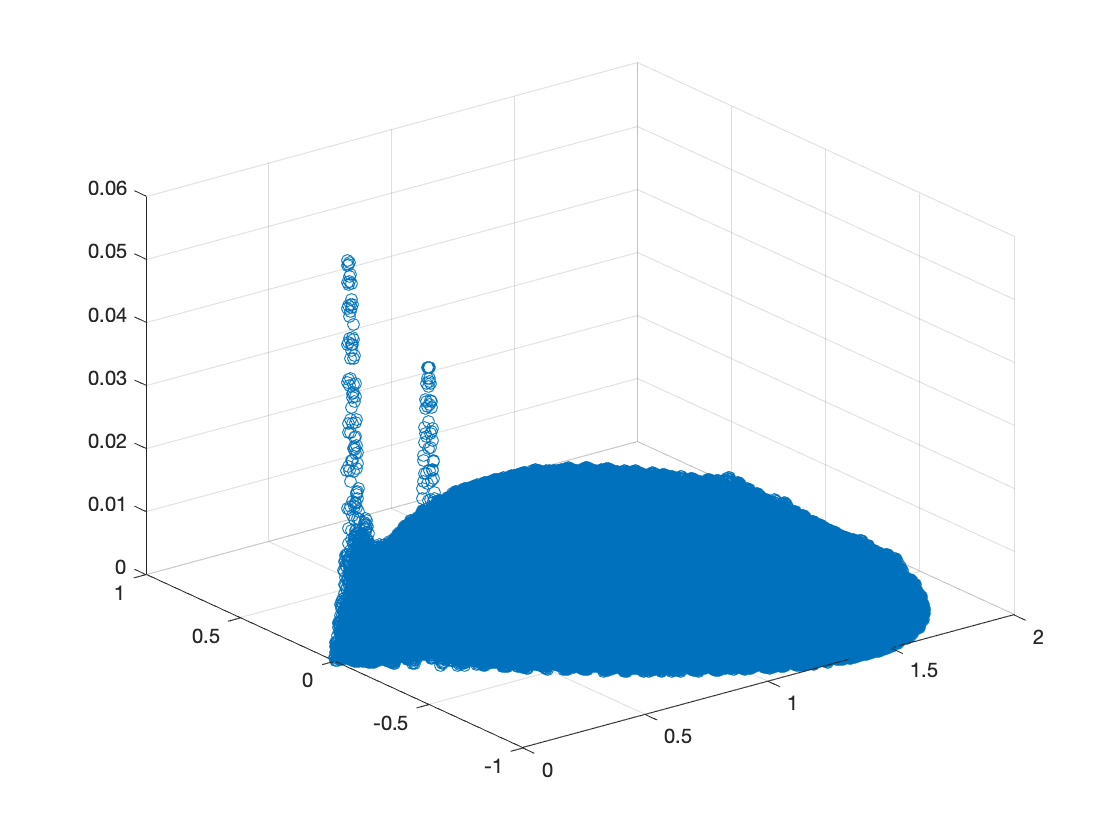

f_exact = f(R_X_err(interior_polygon_err), R_Y_err(interior_polygon_err));

figure;
scatter3(R_X_err(interior_polygon_err), R_Y_err(interior_polygon_err), abs(f_exact-f_numeric(interior_polygon_err)))


f_exact = f(R_X_err(interior_polygon_err), R_Y_err(interior_polygon_err));
max(abs(f_exact-f_numeric(interior_polygon_err)))

ans = 0.0584

err = abs(f_exact-f_numeric(interior_polygon_err))

err =     0.0000
    0.0005
    0.0010
    0.0006
    0.0000
    0.0006
    0.0012
    0.0013
    0.0011
    0.0006


norm_err = err./max(err)

norm_err =     0.0007
    0.0084
    0.0167
    0.0099
    0.0008
    0.0100
    0.0212
    0.0227
    0.0183
    0.0108


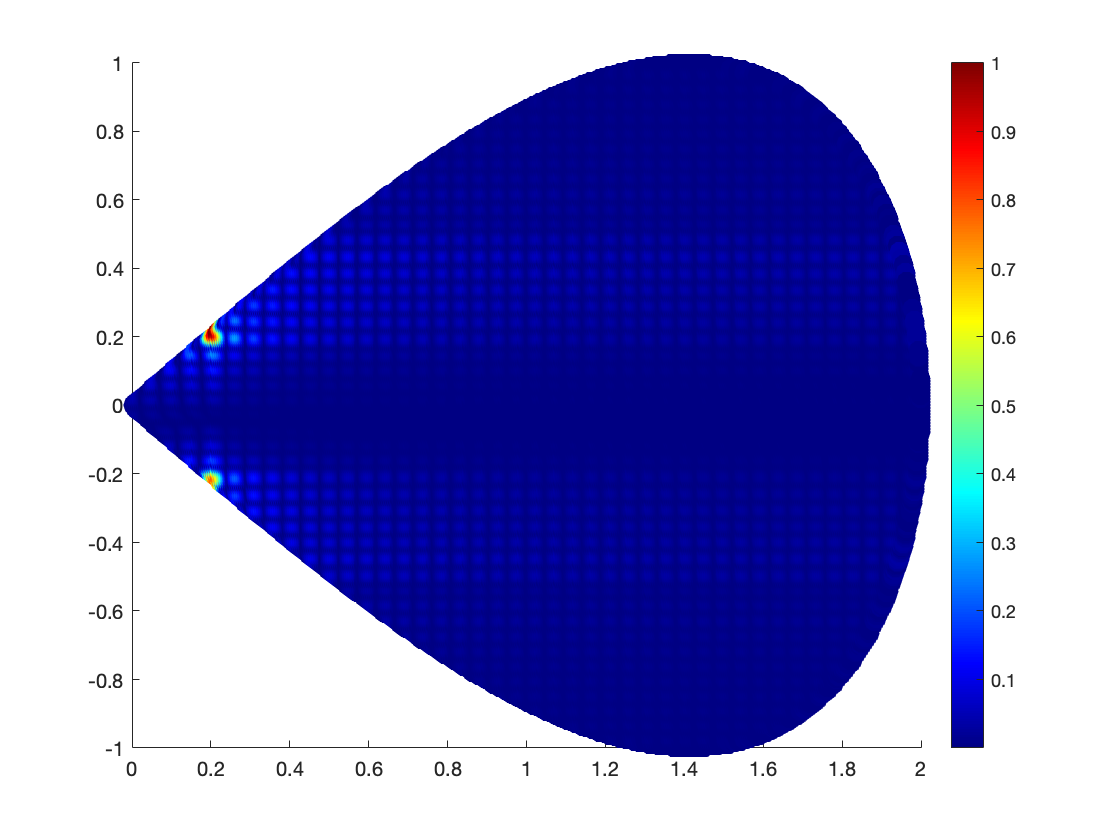


figure;
scatter(R_X_err(interior_polygon_err), R_Y_err(interior_polygon_err), 100, norm_err, 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

# Construction of Patches

Note that these are domain specific functions

function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY); % data associated with patch
end

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h);
end

% function f_y = f(x, y)
%     r = sqrt(x.^2 + y.^2);
%     f_y = zeros(size(x));
%     f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
%     f_y(r >= 0.56) = 0;
% end